# Métodos Numéricos y Programación

*F. Pena*

## Tema 3. Métodos de remonte y descenso

### Método de remonte

La función remonte implementa el método de resolución de sistemas triangulares por remonte, explicado en los apuntes de la materia.

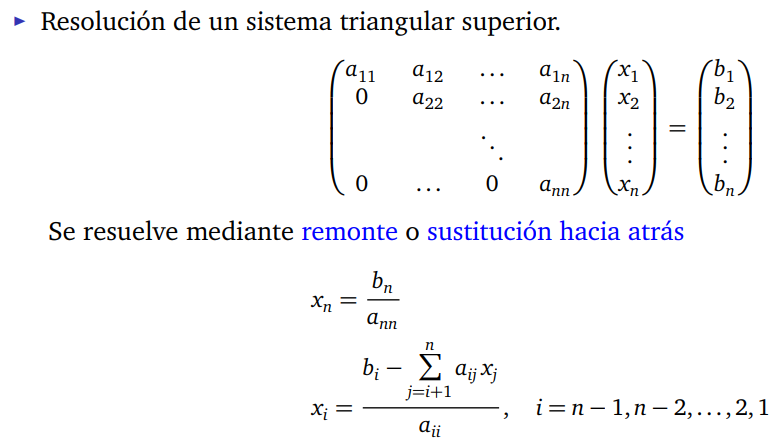

Veamos un ejemplo:

A = [3 2 -1; 0 1 4; 0 0 2];
b = [5 6 4]';
x = remonte(A, b)

x =     3.6667
   -2.0000
    2.0000


residuo = norm(A*x-b)

residuo = 0

Comparemos el tiempo de ejecución de remonte con el operador *backslah* `\` de MATLAB, para matrices densas.

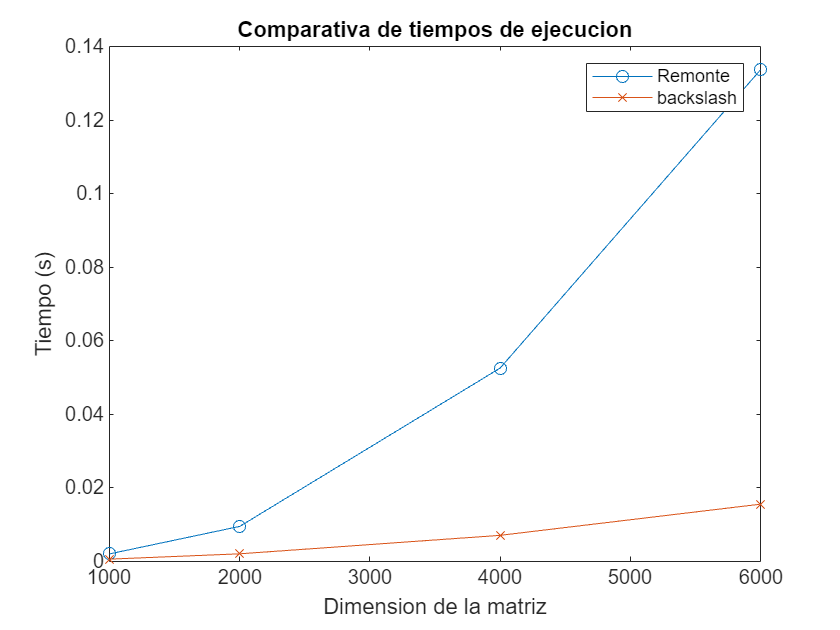

mdim = [1000, 2000, 4000, 6000]; % dimensiones
tr = zeros(size(mdim)); % tiempos para remonte
tb = zeros(size(mdim)); % tiempos para \
rep = 20; % repeticiones por dimension
for i = 1:length(mdim)
    totalr = 0;
    totalb = 0;
    for r = 1:rep
        A = triu(rand(mdim(i))) + 2*eye(mdim(i));
        b = rand(mdim(i), 1);
        % remonte
        tic;
        x = remonte(A, b);
        totalr = totalr + toc;
        % backslash \
        tic;
        x = A \ b;
        totalb = totalb + toc;
    end
    % promedios
    tr(i) = totalr / rep;
    tb(i) = totalb / rep;
end
% grafica de tiempos
plot(mdim, tr, '-o', mdim, tb, '-x')
xlabel('Dimension de la matriz')
ylabel('Tiempo (s)')
title('Comparativa de tiempos de ejecucion')
legend('Remonte', 'backslash')

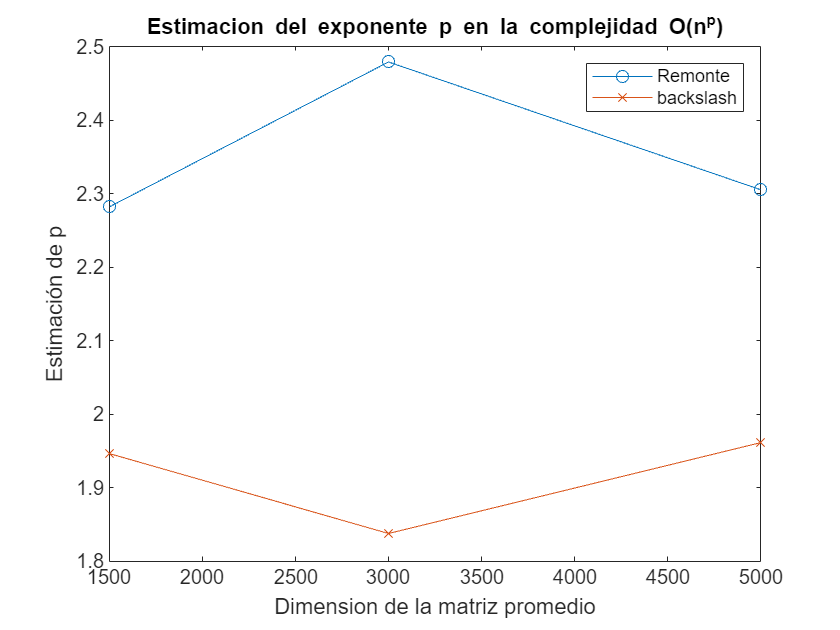

% grafica de estimacion del exponente p de la complejidad O(n^p)
p_estim = @(n,t) log(t(2:end) ./ t(1:end-1)) ./ log(n(2:end) ./ n(1:end-1));
pr = p_estim(mdim, tr);
pb = p_estim(mdim, tb);
mdim_avg = (mdim(2:end) + mdim(1:end-1)) / 2; % tamaño de matriz promedio entre
plot(mdim_avg, pr, '-o', mdim_avg, pb, '-x')
xlabel('Dimension de la matriz promedio')
ylabel('Estimación de p')
title('Estimacion del exponente p en la complejidad O(n^p)')
legend('Remonte', 'backslash')

#### **Ejercicio de cálculo de tiempo de ejecución de remonte para matrices dispersas**

Repite los cálculos anteriores usando matrices dispersas. Toma dimensiones 100, 500, 1000, 2000, y 10 repeticiones por dimensión. Para conseguir matrices sparse inversibles basta usar:

% A_sparse = sprandsym(mdim(i), 0.05, 1, 1); % matriz dispersa, 5% de densidad, simétrica
% I = 2*speye(size(A_sparse)); % valores adicionales en la diagonal
% A = triu(A_sparse + I); % A triangular superior

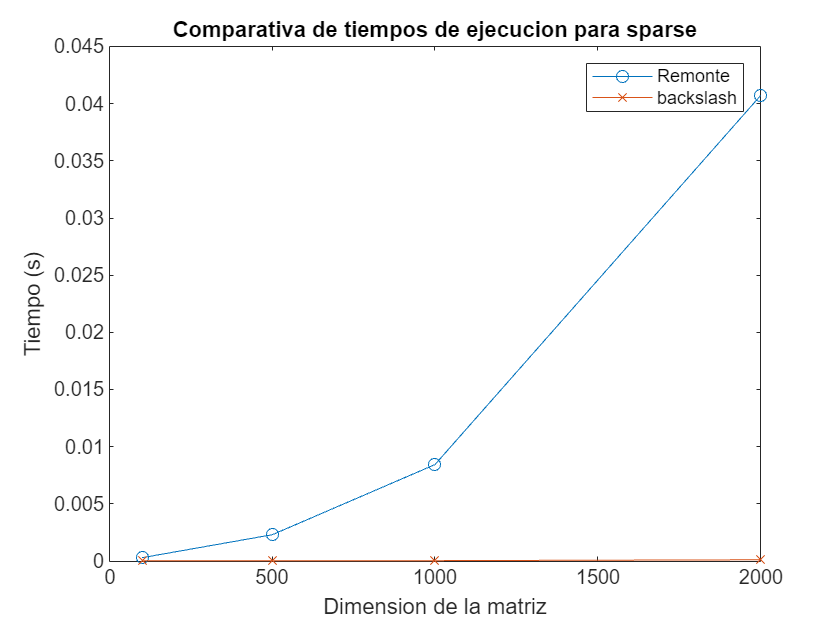

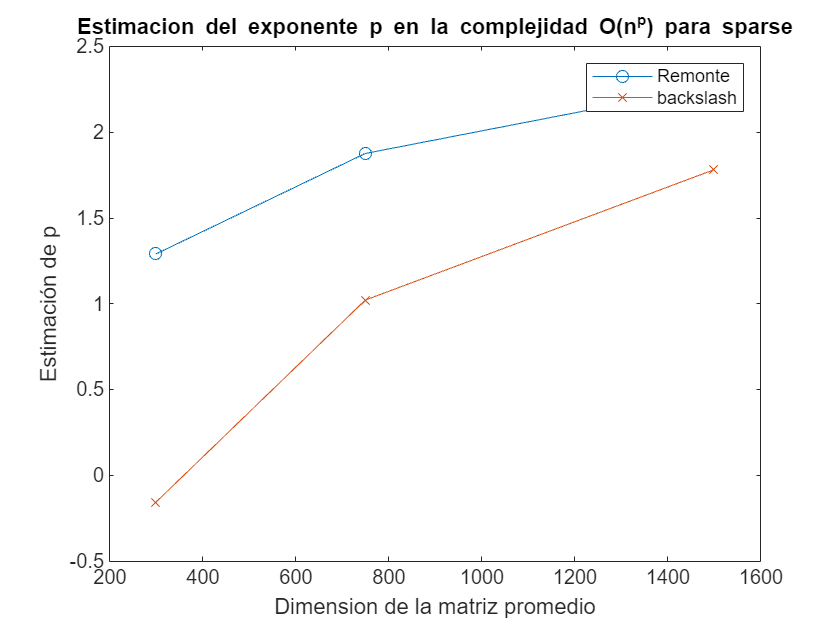

run("../t3_soluciones/solucion4.m")

#### **Ejercicio de cálculo de tiempo de ejecución para el método de descenso**

Repite los cálculos anteriores para el método de descenso:

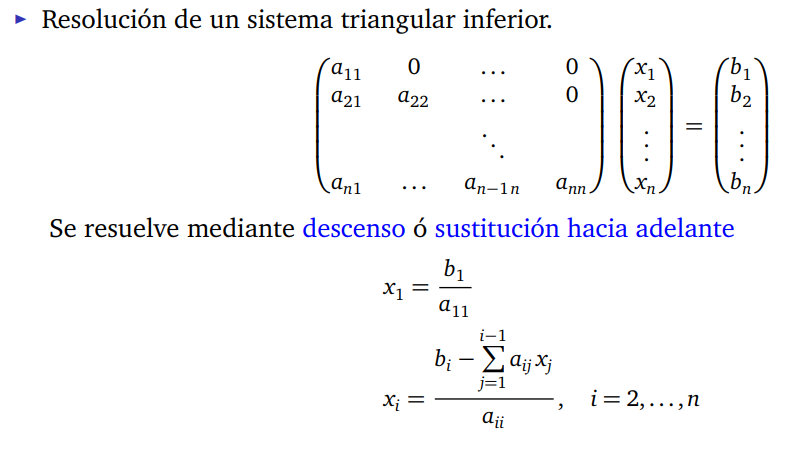

## **Anexo. Funciones locales**

En Matlab, las funciones locales utilizadas en un *script*, van al final de éste.

function x = remonte(A, b)
% remonte - Solución de un sistema de ecuaciones lineales triangular superior
%   usando el método de sustitución hacia atrás.
%
%     x = remonte(A, b) resuelve el sistema de ecuaciones lineales Ax = b,
%     donde A es una matriz triangular superior (nxn) y b es un vector
%     columna (nx1) de términos independientes.
%
%   Ejemplo de uso
%     A = [3, 2, -1; 0, 1, 4; 0, 0, 2];
%     b = [5; 6; 4];
%     x = remonte(A, b)
%
%   Limitaciones
%     - La matriz A debe ser triangular superior. Si se proporciona una
%       matriz que no sea triangular superior, la función generará un error.
    arguments
        A (:,:) double {mustBeNumeric, mustBeTriangularUpper}
        b (:,1) double {mustBeNumeric}
    end
    n = length(b);
    x = zeros(n, 1);
    x(n) = b(n) / A(n, n);

    for i = n-1:-1:1
        x(i) = (b(i) - A(i, i+1:n) * x(i+1:n)) / A(i, i);
    end
end

function mustBeTriangularUpper(A)
% Función de validación que verifica si la matriz es triangular superior
    if ~istriu(A)
        error('La matriz A debe ser triangular superior.');
    end
end